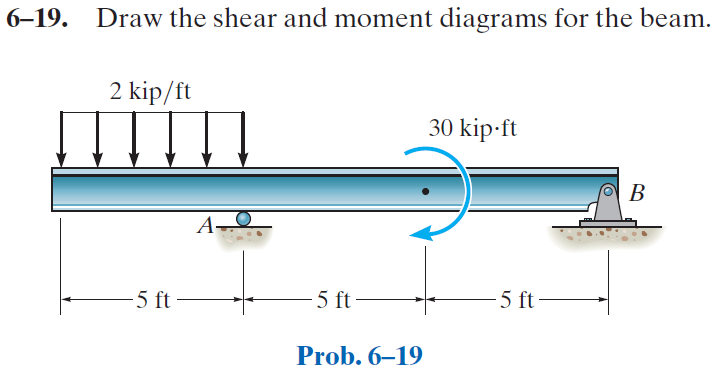

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-19P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-19P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 5*u.ft);
b = b.add('reaction', 'force', 'Rb', 15*u.ft);
b = b.add('concentrated', 'moment', -30*u.kip*u.ft, 10*u.ft);
b = b.add('distributed', 'force', -2*u.kip/u.ft, [0 5]*u.ft);
b.L = 15*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\left(x-5\,\mathrm{ft}\right)\,\left(x^{3}+5\,x^{2}\,\mathrm{ft}+25\,x\,{\mathrm{ft}}^{2}-1525\,{\mathrm{ft}}^{3}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{\left(x-5\,\mathrm{ft}\right)\,\left(x^{2}+140\,x\,\mathrm{ft}-1875\,{\mathrm{ft}}^{2}\right)}{12\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(5\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{\left(x-15\,\mathrm{ft}\right)\,\left(x^{2}-30\,x\,\mathrm{ft}+575\,{\mathrm{ft}}^{2}\right)}{12\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{825\,{\mathrm{ft}}^{3}-2\,x^{3}}{6\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{3\,x^{2}+270\,x\,\mathrm{ft}-2575\,{\mathrm{ft}}^{2}}{12\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(5\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{3\,x^{2}-90\,x\,\mathrm{ft}+1025\,{\mathrm{ft}}^{2}}{12\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -x^{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{x+45\,\mathrm{ft}}{2}\,\mathrm{kip} & \text{ if }x\in \left(5\,\mathrm{ft},10\,\mathrm{ft}\right]\\ -\frac{x-15\,\mathrm{ft}}{2}\,\mathrm{kip} & \text{ if }10\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -2\,x\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{1}{2}\,\mathrm{kip} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -2\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ 0 & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 9.5\,\mathrm{kip}\\ \mathrm{Rb} & 0.5\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

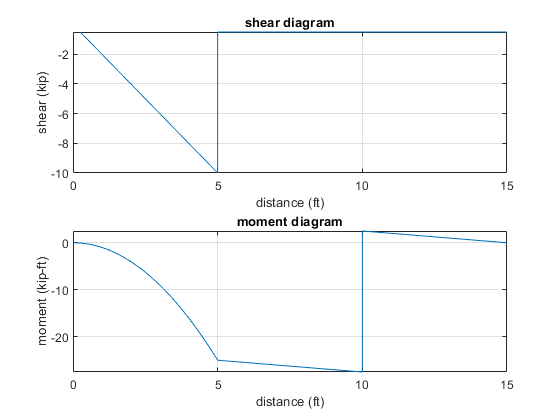

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;